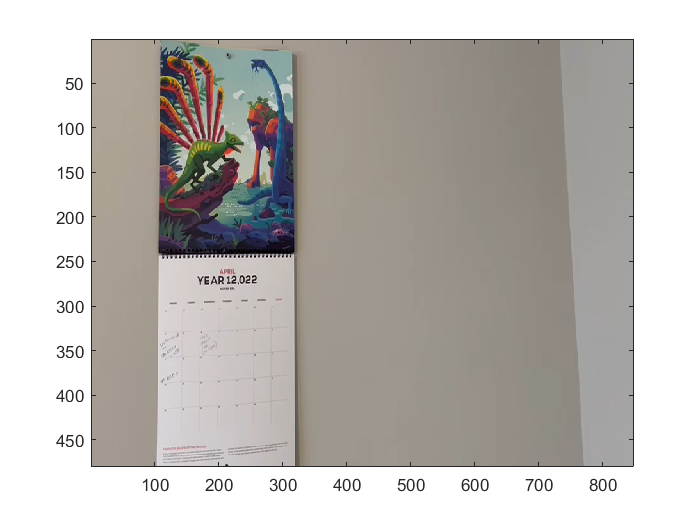

vReader = VideoReader('C:\Users\pooja\Downloads\video.mp4','CurrentTime',1);
numFrames = vReader.NumFrames;
n=numFrames;
for i = 1:2:n
    pictureframes = read(vidReader,i);
    imwrite(pictureframes,['Image' int2str(i), '.jpg']);
    imageloop(i)=image(pictureframes);
end

calendar = im2gray(imread('C:\Users\pooja\Desktop\Images\Image3.jpg'));
dates = im2gray(imread('C:\Users\pooja\Desktop\Images\Image299.jpg'));
thisFrame = dates;
imshow(thisFrame);
axis on;
set(gcf, 'Position', get(0,'Screensize')); % Maximize figure.    
h_rect = drawrectangle('Label','REGION OF INTEREST','Color',[1 1 1]);
position_rect = h_rect.Position();
% Round off so the coordinates can be used as indices
position_rect = round(position_rect);
close(gcf)
thisFrame = imcrop(thisFrame,position_rect);
dates = thisFrame

dates = 205×195 uint8 matrix
   211   211   211   211   211   211   211   211   212   212   212   212   212   212   212   212   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   209   209   208   208   208   210   210   210   209   209   208   208   208   208   208
   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   211   211   211   211   211   211   211   211   210   210   210   210   210   210   210   210   210   210   210   209   209   208   208   208   210   210   210   209   209   208   208   208   208   208
   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   211   211   211   211   211   211   211   211   210   210   210   210   210   210   210   210   210   210   210   209   209   208   208   208   210   210   210   209   209   208   208   208   208   208
   213   213   213   213   213   213   213   213   212   212   212  

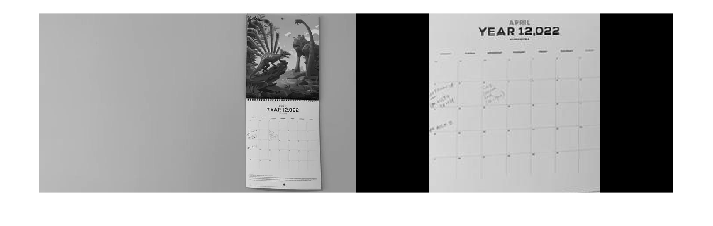

montage({calendar,dates})

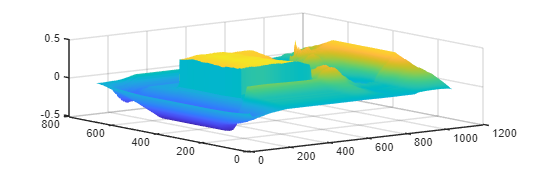

c = normxcorr2(dates,calendar);
surf(c)
shading flat

[ypeak,xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(dates,1);
xoffSet = xpeak-size(dates,2)

xoffSet = 552

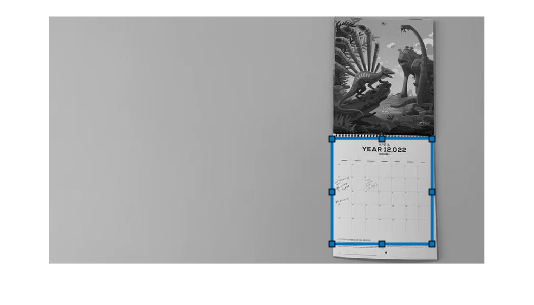

imshow(bottle)
drawrectangle(gca,'Position',[xoffSet,yoffSet,size(dates,2),size(dates,1)], ...
    'FaceAlpha',0);